
syms L1 L2 C1 RL s

% ZL1 = L1 * s;
% ZL2 = L2 * s;
% ZC1=( (C1*s) + 1/( 4 + 1/(C1*s*1e1) ) )^-1;
% ZRL = RL;
% 
% Z1 = ZL2 + ZRL;
% Z2 = (Z1 * ZC1) / (Z1 + ZC1);
% 
% LCLR = Z2 / (ZL1 + Z2);
% LCLR = collect(LCLR);

% Analyze for two different values of RL
L1_val = 1e-6;
L2_val = 1.5e-6;
C1_val = 70e-12;
RL_val = 1e6;
analyze_LCLR(L1_val, L2_val, C1_val, RL_val);

$$polyN = \left(\begin{array}{cc} 200\,C_{1}\,s+1 & \mathrm{RL}+L_{2}\,s \end{array}\right)$$

$$polyD = \mathrm{RL}+L_{1}\,s+L_{2}\,s+200\,C_{1}\,\mathrm{RL}\,s+200\,C_{1}\,L_{1}\,s^{2}+200\,C_{1}\,L_{2}\,s^{2}+C_{1}\,L_{1}\,L_{2}\,s^{3}+C_{1}\,L_{1}\,\mathrm{RL}\,s^{2}$$

fcut = 2.4558e+07

R_damp = 1.2183e+03

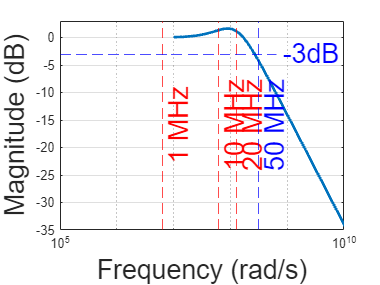

% 
hold on;

$$polyN = \left(\begin{array}{cc} 200\,C_{1}\,s+1 & \mathrm{RL}+L_{2}\,s \end{array}\right)$$

$$polyD = \mathrm{RL}+L_{1}\,s+L_{2}\,s+200\,C_{1}\,\mathrm{RL}\,s+200\,C_{1}\,L_{1}\,s^{2}+200\,C_{1}\,L_{2}\,s^{2}+C_{1}\,L_{1}\,L_{2}\,s^{3}+C_{1}\,L_{1}\,\mathrm{RL}\,s^{2}$$

fcut = 2.4558e+07

R_damp = 1.2183e+03

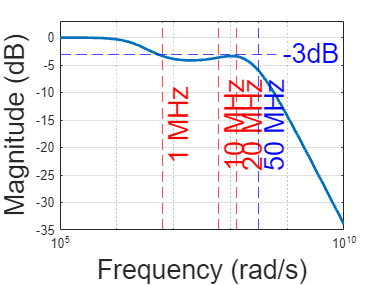


RL_val = 6.8e0;
analyze_LCLR(L1_val, L2_val, C1_val, RL_val);

$$polyN = \left(\begin{array}{cc} 200\,C_{1}\,s+1 & \mathrm{RL}+L_{2}\,s \end{array}\right)$$

$$polyD = \mathrm{RL}+L_{1}\,s+L_{2}\,s+200\,C_{1}\,\mathrm{RL}\,s+200\,C_{1}\,L_{1}\,s^{2}+200\,C_{1}\,L_{2}\,s^{2}+C_{1}\,L_{1}\,L_{2}\,s^{3}+C_{1}\,L_{1}\,\mathrm{RL}\,s^{2}$$

fcut = 2.4558e+07

R_damp = 1.2183e+03

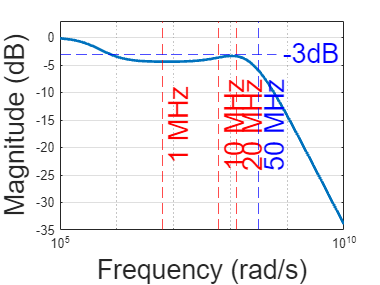



RL_val = 1e0;
analyze_LCLR(L1_val, L2_val, C1_val, RL_val);

function [polyN,polyD]=analyze_LCLR(L1_val, L2_val, C1_val, RL_val)
    % Define symbolic variables
    syms L1 L2 C1 RL s

    % Define impedances
    ZL1 = L1 * s;
    ZL2 = L2 * s;
    ZC1 = ((200+1/(C1*s)) );
    ZRL = (1/RL)^-1;

    % ZL1 = L1 * s;
    % ZL2 = L2 * s;
    % ZC1 = ((C1 * s) )^-1;
    % ZRL = (1/RL+1/(1e1+1/(C1*s*0.5e2)))^-1;
     

    % Set up the circuit expressions
    Z1 = ZL2 + ZRL;
    Z2 = (Z1 * ZC1) / (Z1 + ZC1);
    LCLR = Z2 / (ZL1 + Z2);
    [symN,symD]=numden(LCLR);
    polyN=factor(symN,s)
    polyD=factor(symD,s)



    fcut=1/(2*pi)*sqrt((L1_val+L2_val)/(L1_val*L2_val*C1_val))
    R_damp=2*pi/(3*fcut*C1_val)
    % Substitute numerical values for constants
    LCLR = subs(LCLR, {L1, L2, C1, RL}, {L1_val, L2_val, C1_val, RL_val});
    
    % Extract numerator and denominator of the symbolic transfer function
    [num, den] = numden(LCLR);
    % factor(num)
    % factor(den)

    % Convert the symbolic numerator and denominator to polynomial coefficients
    num_coeffs = sym2poly(num);
    den_coeffs = sym2poly(den);

    % Create the transfer function
    tf_LCLR = tf(num_coeffs, den_coeffs);

    % Display the transfer function
    %disp('Transfer function LCLR(s):');
    %disp(tf_LCLR);

    % Create the Bode plot and overlay the -3 dB cutoff line
    % figure;
    % h = bodeplot(tf_LCLR); % Use bodeplot for better control
    % title('Bode Plot of LCLR(s)');
% 
%     % Convert magnitude data to dB for setting up the cutoff line
    [mag, ~, w] = bode(tf_LCLR);
    mag_dB = 20 * log10(squeeze(mag));
    cutoff_dB = -3;  % -3 dB cutoff line

    % Access the magnitude axis from the bodeplot handle
    %ax = findobj(h, 'Type', 'axes', '-and', 'YLabel', 'Magnitude (dB)');

    figure;
    % Plot the -3 dB cutoff line on the magnitude plot
    semilogx(w,mag_dB,'LineWidth',2)
    xlim([1e5 1e10]);
    ylim([-35 3]);
    
    %set(gca, 'YLim', [-10, 5]);
    hold on;
    %semilogx(w, (cutoff_dB * ones(size(w))+mag_dB(1)),'LineWidth',2);

    % Add vertical lines at 20 MHz and 50 MHz
    xline(2 * pi * 1e6, '--r', '1 MHz', 'LabelVerticalAlignment', 'middle', 'FontSize', 10 * 2);
    xline(2 * pi * 10e6, '--r', '10 MHz', 'LabelVerticalAlignment', 'middle', 'FontSize', 10 * 2);
    xline(2 * pi * 20e6, '--r', '20 MHz', 'LabelVerticalAlignment', 'middle', 'FontSize', 10 * 2);
    xline(2 * pi * 50e6, '--b', '50 MHz', 'LabelVerticalAlignment', 'middle', 'FontSize', 10 * 2);
    yline(-3, '--b', '-3dB', 'LabelVerticalAlignment', 'middle', 'FontSize', 10 * 2);


    % Customize labels and grid
    xlabel('Frequency (rad/s)');
    ylabel('Magnitude (dB)');
    grid on;
    set(get(gca, 'YLabel'), 'FontSize', 10 * 2);
    set(get(gca, 'XLabel'), 'FontSize', 10 * 2);
    grid on;
    %hold off;
end

